## Smoothing funkcija

function res = pogladkaj(vec, window_size)
    vec_len = length(vec); % dolzina vektorja

    if window_size < 7 || mod(window_size, 2) == 0
        disp('Dolzina window_size mora biti liha in večja od 7.');
        return
    end

    res = NaN(vec_len, 1); % vektor za rezultate
    utezi = NaN(window_size, 1); % vektor za uteži
    middle = ceil(window_size / 2); % sredina weights (ali window)

    % izračunamo weights s pomočjo fibonacci funkcije
    % fib..(1) in fib..(2) vrneta 1, zato začnemo s fib..(2)
    for i = 1 : window_size
        utezi(i) = fibonacci(i + 1);
    end

    % shranimo polovico utezi, ker jih toliko potrebujemo
    utezi = utezi(1:middle);

    % poračunamo nove (smoothed) vrednosti, tako da gremo čez vse
    % vrednosti v vektorju. začnemo pri `sredinskem` elementu 
    % glede na middle in končamo vec_len - middle
    for i = middle : vec_len - middle + 1
        % loopamo čez vsak weight in poračunamo posamezno vrednost
        % za neke elemente v vektorju s pomočjo window in jo dodamo v tmp
        tmp = 0;
        for j = 1 : middle
            if j == middle
                utezi = flip(utezi);
            end

            % prva iteracija: 3 + 1 - 3 = 1, torej dobimo prvi element
            cur_element = vec(i + j - middle); 
            cur_weight = utezi(j);

            tmp = tmp + cur_element * cur_weight;
        end

        % poračunamo povprečje
        res(i) = tmp / sum(utezi);
    end
end

## Primer uporabe/dokaz delovanja

Preberemo in pripravimo podatke

temp = readtable('data.csv');
data = table2array(temp);
t = data(:, 1); % time
x = data(:, 2); % displacement
dt = t(2) - t(1); % neka razlika idk

Uporabimo funkcijo, da dobimo nove *poglajene* podatke.

window_size = 7;
x_smooth_3 = pogladkaj(x, window_size);

v___ = diff(x_smooth_3)/dt;
a___ = diff(v___)/dt;

v_smooth_3 = pogladkaj(v___, window_size);
a_smooth_3 = pogladkaj(a___, window_size);

popravimo NaN vrednosti, idk

for i = 1 : length(x_smooth_3)
    if isnan(x_smooth_3(i))
        x_smooth_3(i) = 0;
    end
end

for i = 1 : length(v_smooth_3)
    if isnan(v_smooth_3(i))
        v_smooth_3(i) = 0;
    end
end

for i = 1 : length(a_smooth_3)
    if isnan(a_smooth_3(i))
        a_smooth_3(i) = 0;
    end
end

Izrišemo grafe

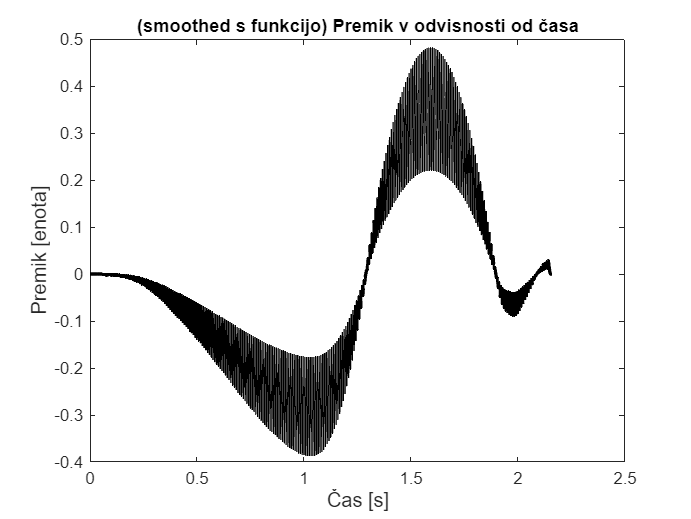

figure
plot(t, x_smooth_3, 'k', 'LineWidth', 2) % premik ~ čas
ylabel('Premik [enota]','FontSize',12)
xlabel('Čas [s]','FontSize',12)
title('(smoothed s funkcijo) Premik v odvisnosti od časa')


disp(x_smooth_3);

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
   -0.0009
   -0.0007
   -0.0018
   -0.0013
   -0.0027
   -0.0011
   -0.0024
   -0.0009
   -0.0018
   -0.0013
   -0.0027
   -0.0013
   -0.0027
   -0.0013
   -0.0027
   -0.0013
   -0.0027
   -0.0013
   -0.0036
   -0.0020
   -0.0045
   -0.0025
   -0.0055
   -0.0025
   -0.0055
   -0.0027
   -0.0067
   -0.0036
   -0.0082
   -0.0039
   -0.0088
   -0.0044
   -0.0105
   -0.0052
   -0.0114
   -0.0059
   -0.0135
   -0.0068
   -0.0150
   -0.0072
   -0.0163
   -0.0083
   -0.0190
   -0.0094
   -0.0214
   -0.0103
   -0.0227
   -0.0114
   -0.0254
   -0.0127
   -0.0285
   -0.0140
   -0.0313
   -0.0153
   -0.0340
   -0.0165
   -0.0376
   -0.0184
   -0.0405
   -0.0195
   -0.0427
   -0.0206
   -0.0454
   -0.0223
   -0.0499
   -0.0241
   -0.0532
   -0.0256
   -0.0565
   -0.0275
   -0.0604
   -0.0293
   -0.0649
   -0.0313
   -0.0695
   -0.0337
   -0.0734

disp(v_smooth_3);

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
   -0.0198
   -0.0198
   -0.0516
   -0.0754
   -0.0397
    0.0317
    0.0278
    0.0516
    0.0555
   -0.0238
   -0.0040
    0.0317
    0.0119
    0.0317
    0.0317
    0.0317
    0.0317
    0.0317
    0.0119
    0.0119
   -0.0198
   -0.0436
   -0.0079
    0.0436
    0.0436
    0.0436
    0.0278
    0.0238
   -0.0119
    0.0337
    0.0417
    0.0555
    0.0377
    0.0655
    0.0417
    0.0060
    0.0357
    0.0833
    0.0476
    0.1031
    0.1031
    0.0952
    0.0635
    0.1150
    0.0754
    0.1468
    0.1408
    0.1131
    0.1369
    0.1527
    0.1190
    0.1964
    0.1607
    0.2182
    0.2023
    0.2499
    0.2142
    0.2817
    0.2400
    0.2876
    0.3233
    0.3590
    0.3491
    0.3471
    0.3114
    0.4245
    0.3531
    0.4106
    0.4225
    0.4443
    0.4344
    0.4860
    0.4582
    0.5693
    0.4919
    0.5455
    0.5415
    0.6188

disp(a_smooth_3);

   1.0e+03 *

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
   -0.0238
   -0.0086
   -0.0362
   -0.0048
   -0.0267
   -0.0048
   -0.0324
   -0.0095
    0.0019
   -0.0162
   -0.0029
   -0.0133
   -0.0390
   -0.0105
   -0.0152
   -0.0152
   -0.0152
   -0.0152
   -0.0390
   -0.0238
   -0.0514
   -0.0200
   -0.0419
   -0.0209
   -0.0495
   -0.0267
   -0.0562
   -0.0400
   -0.0838
   -0.0348
   -0.0824
   -0.0428
   -0.0914
   -0.0562
   -0.1014
   -0.0552
   -0.1033
   -0.0685
   -0.1409
   -0.0685
   -0.1333
   -0.0866
   -0.1580
   -0.0971
   -0.1999
   -0.1038
   -0.1814
   -0.1166
   -0.1799
   -0.1328
   -0.2409
   -0.1419
   -0.2647
   -0.1566
   -0.2656
   -0.1742
   -0.3047
   -0.1971
   -0.3185
   -0.2033
   -0.3009
   -0.2233
   -0.3180
   -0.2418
   -0.3751
   -0.2613
   -0.4227
   -0.2718
   -0.4003
   -0.2989
   -0.4265
   -0.3151
   -0.4803
   -0.3399
   -0.5298
   -0.3651
   -0.5136
   -0.3

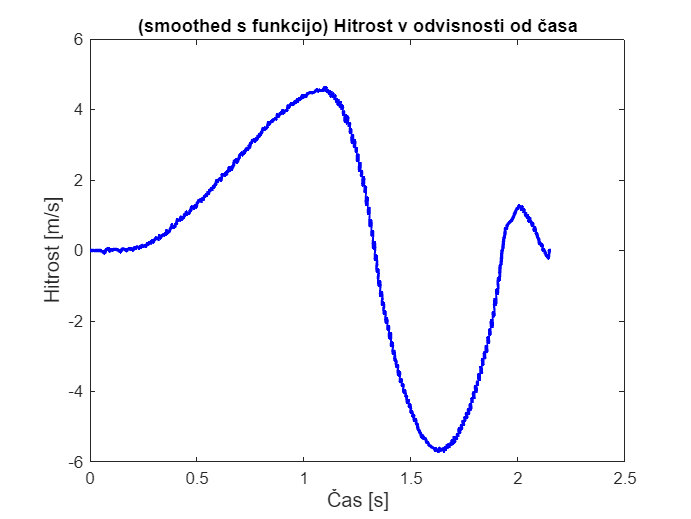


figure
plot(t(1:end - 1), v_smooth_3, 'b', 'LineWidth', 2) % hitrost ~ čas
ylabel('Hitrost [m/s]','FontSize',12)
xlabel('Čas [s]','FontSize',12)
title('(smoothed s funkcijo) Hitrost v odvisnosti od časa')

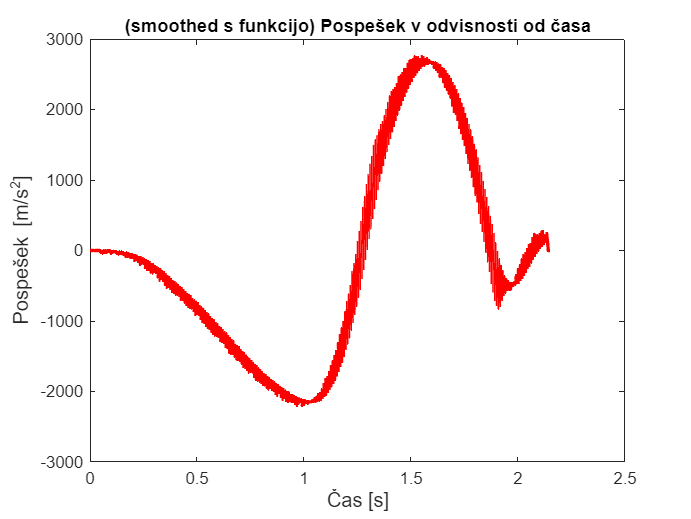


figure
plot(t(1:end - 2), a_smooth_3, 'r', 'LineWidth', 2) % pospešek ~ čas
ylabel('Pospešek [m/s^2]','FontSize',12)
xlabel('Čas [s]','FontSize',12)
title('(smoothed s funkcijo) Pospešek v odvisnosti od časa')